# Roordalab Custom Shack-Hartmann Sensor

Data-reduction pipeline for processing spot-field images

clearvars
close all

A raw Shack-Hartmann spot field image of just a single megapixel contains over a million numbers. The process of reducing this massive amount of data into either a wavefront "surface" sampled over a grid of a few hundred points or a set of polynomial coefficients for a model representation is known as *data reduction*.

measurementFileName = "R25M0005g.tif";  

#### Recommendation

- Scale down for image preprocessing such that either dimension doesn't exceed 256 pixels

## 1) Preprocessing 

First preprocess the Shack-Hartmann spot field image to help isolate contents of interest. If background image is available, alway subtract background. Negative pixel values may appear due to sensor noise; they shall be zeroed. 

% load background and measurement images
bkgd = imread("background.tif");
meas = imread(measurementFileName);
I = uint8(meas - bkgd); % Forcing uint8 zeroes negative values

Rescale image to a quarter the original size image processing

I = imresize(I, 0.25, "AntiAliasing", true);

### 1.1 Thresholding

Assume hardware is designed such that it's NOT possible for significant straylight to land on non-pupil pixels. Therefore, pixels outside of system aperture $\Sigma$ defines detector noise. Let's call them* mask pixels*. 


$$T(x,y)=f_0(x,y)+T_0$$


Use Gonzalez and Wood's (2002) iterative threshold to calculate $T_0$ but applied to mask pixels

[rows, cols] = size(I);
a = 0.5 * (min(rows, cols) + 1);
[X, Y] = meshgrid(1:cols,1:rows);
R = sqrt((X - 0.5*(cols + 1)).^2 + (Y - 0.5*(rows + 1)).^2);
mask = R > (a-1);
%To = min(nonPupilPixels);
Io = GWE.imopen(I, 5);
I = I - Io; % top hat
% max(T(:))
% max(I(:))

% Open the image, erode followed by dilation


Pupil Estimation.

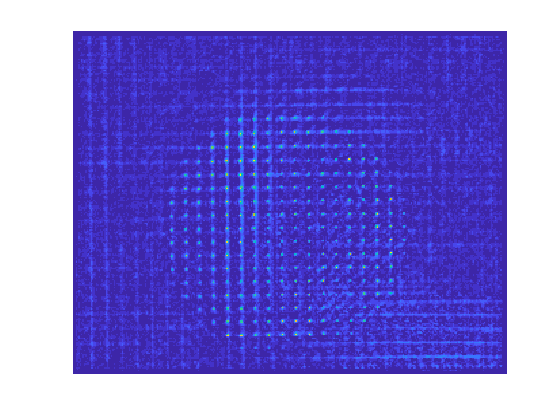

% Divide rescaled image into 4 quadrants and apply threshold
% imcenter = 0.5 * size(I);

imagesc(I), axis off

hold on
hold off

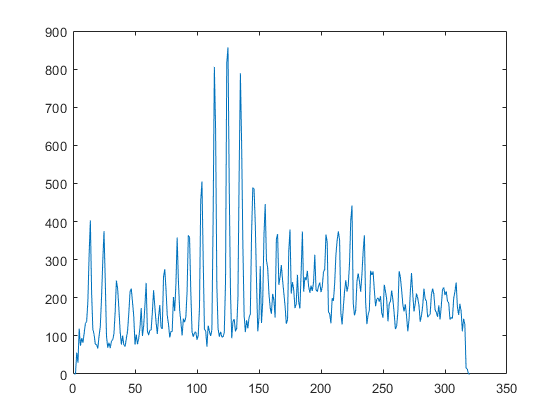

f = sum(I);
plot(f)

% create Shack-Hartmann sensor model
% model = Roorda(bkgd);
% model.process(meas);
% model.show()

## 2) Spot Sorting

Row and column reduction followed by peak analysis. If manual alignment of individual devices 

## 3) Centroiding

## Reconstruction

Wavefront slopes followed by regression

Determine the optimal threshold parameter(s) to isolate pupil in spot-field image

clearvars
close all
sensitivity = 0.3;  

% load images, subtract background, and resize
bkgd = imread("background.tif");
images = {imread("R25M0004g.tif"), imread("R25M0005g.tif"), imread("R25M0006g.tif")}';
binImages = cell(3,1);
for ind = 1:length(images)
    images{ind} = imresize(imsubtract(images{ind}, bkgd), 0.25, "AntiAliasing", true);
    binImages{ind} = imbinarize(images{ind}, "adaptive", "Sensitivity", sensitivity);
end
montage([images, binImages] , "Size", [2 length(images)])